# Transient response of aquifer to polar recharge on spherical cap

set_demo_defaults
theta_p = deg2rad(1);
theta_b = pi-acos(1/3);
theta_ana = linspace(theta_p,theta_b,100);

### Bounding steady solutions

To illustrate the transient solution we consider an aquifer on a spherical cap with precipitation that suddenly experiences polar recharge due to the onset of basal melting of the ice sheet. At the onset of recharge the head in the aquifer is the steady head due only to precipitation

$h'_\mathrm{pre} =\log\left(\frac{\sin\theta}{\sin\theta_p}\right)+\cos\theta_p\log\left(\frac{\csc\theta+\cot\theta}{\csc\theta_b+\cot\theta_b}\right)$, 

hD_pre = @(theta) log(sin(theta)/sin(theta_b))+cos(theta_p)*log((csc(theta)+cot(theta))/(csc(theta_b)+cot(theta_b)));

and that will form the initial condition, $h(\theta,t=0) = h_\mathrm{precip}(\theta)$. In the long-term limit the solution will asymptote to the steady solution with both precipitation and recharge which can be obtained by linear superposition of $h_\mathrm{precip}$ with a solution that has only polar recharge

$h'_\mathrm{rec} = \Pi\sin\theta_p\log\left(\frac{\csc\theta+\cot\theta}{\csc\theta_b+\cot\theta_b}\right)$,

hD_rec = @(theta,Pi) Pi*sin(theta_p)*log((csc(theta)+cot(theta))/(csc(theta_b)+cot(theta_b)));

so that the long-term limit is given by


$$\lim_{t\rightarrow\infty} h'_\mathrm{ful} = h'_\mathrm{pre}+h'_\mathrm{rec}$$


hD_ful = @(theta,Pi) hD_rec(theta,Pi) + hD_pre(theta);

Here we have chosen the precipitations scale for the head, $h_c = q_pR^2/(Kb)$ and the abound of recharge relative to precipitation is given by $\Pi = q_i b/(q_p R)$.

These two bounding solutions can be seen in the figure below for $\Pi=3$

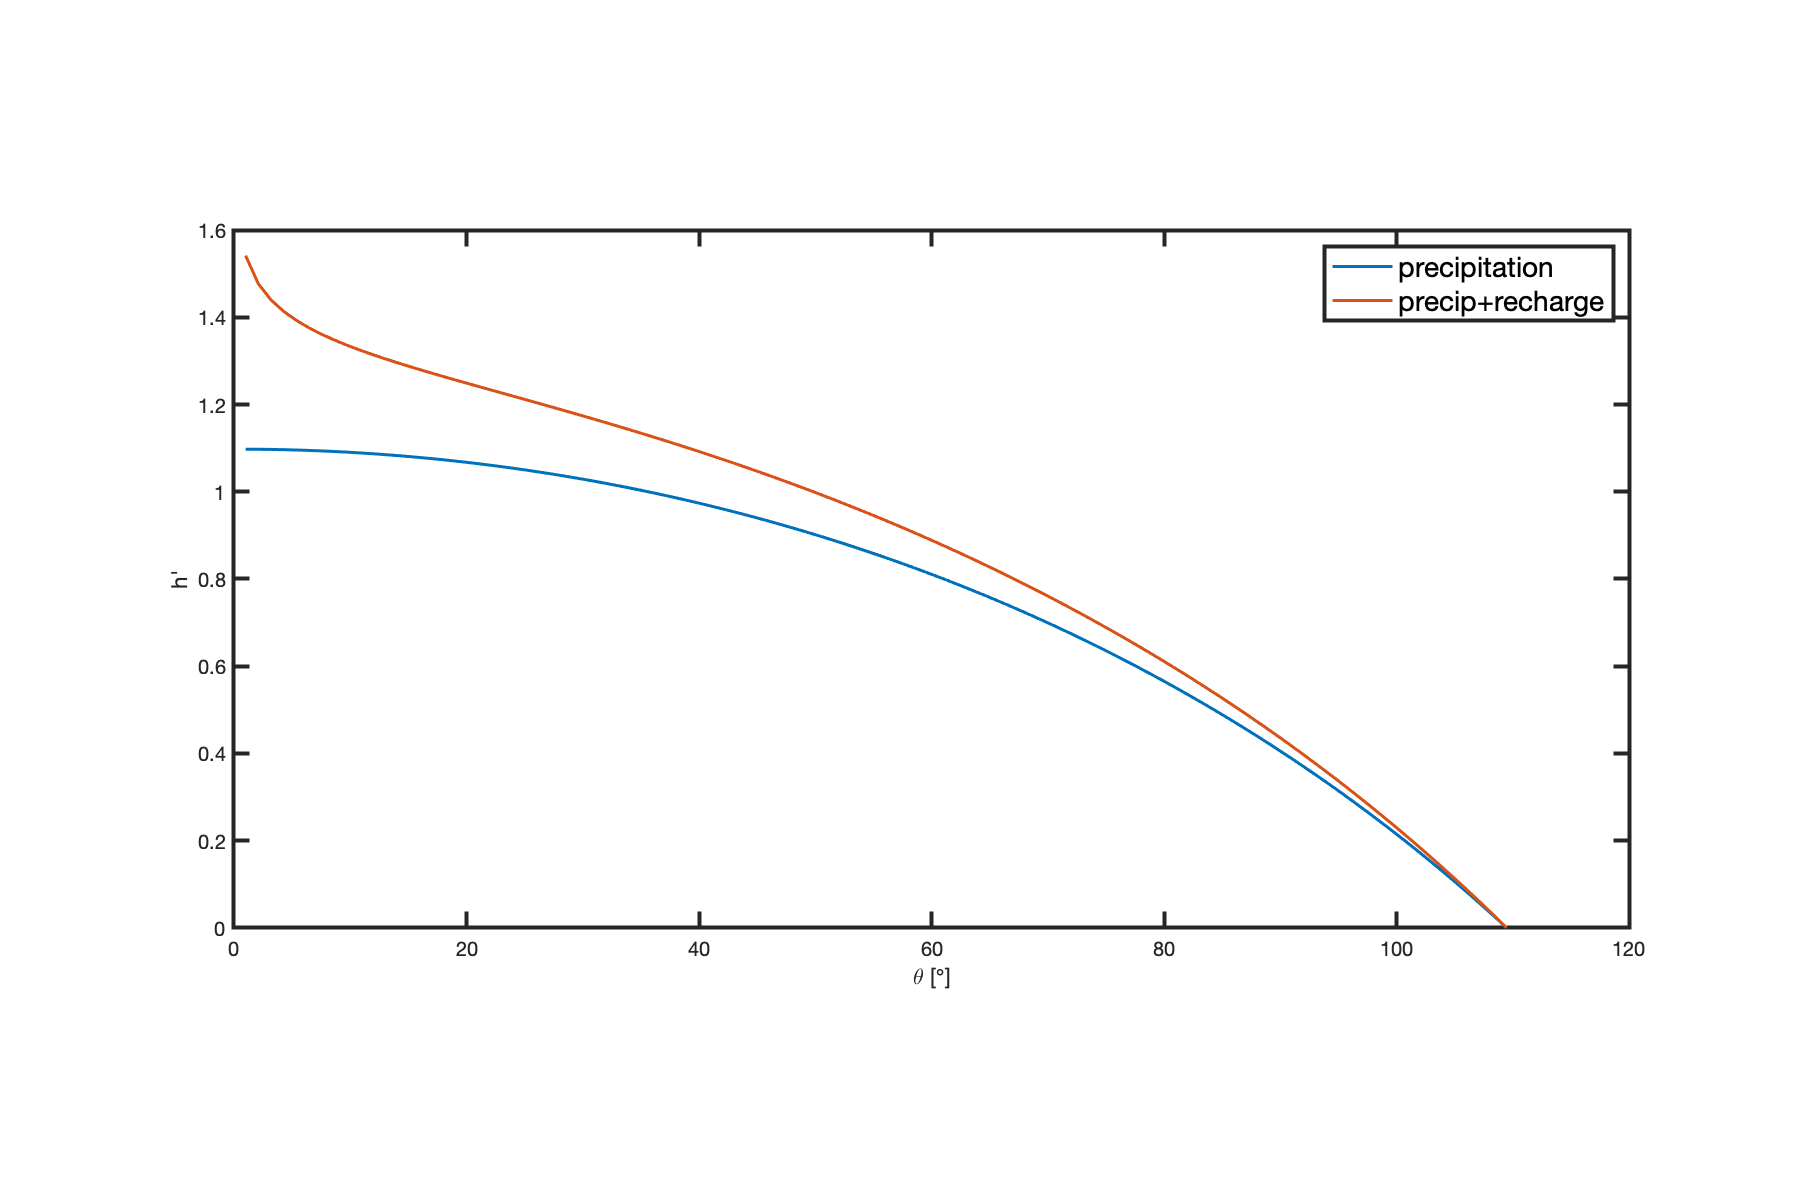

Pi = 5;
figure('position',[10 10 900 600])
plot(rad2deg(theta_ana),hD_pre(theta_ana),'-','linewidth',1.5), hold on
plot(rad2deg(theta_ana),hD_ful(theta_ana,Pi),'-','linewidth',1.5)
xlabel('\theta [\circ]','fontsize',16)
ylabel('h''','fontsize',16)
pbaspect([1 .5 1])
legend('precipitation','precip+recharge','fontsize',14)

## Transient solution

### Problem statement

The dimensionless transient problem is given by the following **I**nitial and **B**oundary **V**alue **P**roblem (**IBVP**)

PDE: $\frac{\partial h'}{\partial t'}-\nabla'\cdot\nabla'h'=1$ on $\theta\in\left[\theta_p,\,\theta_b\right]$,

BC's: $\left.\mathbf{q}'\cdot\hat{\mathbf{n}}\right|_{\theta_p}=-\left.\frac{\partial h'}{\partial \theta}\right|_{\theta_p}=\Pi$ and $h'(\theta_b) = 0$,

IC: $h'(\theta,t'=0) = h'_\mathrm{pre}(\theta)$.

We have chosen the diffusive timescale $t_c = R^2/D_\mathrm{hyd}$, where $D_\mathrm{hyd}=S_s/K$ is the hydraulic diffusivity.

### Numerical solution

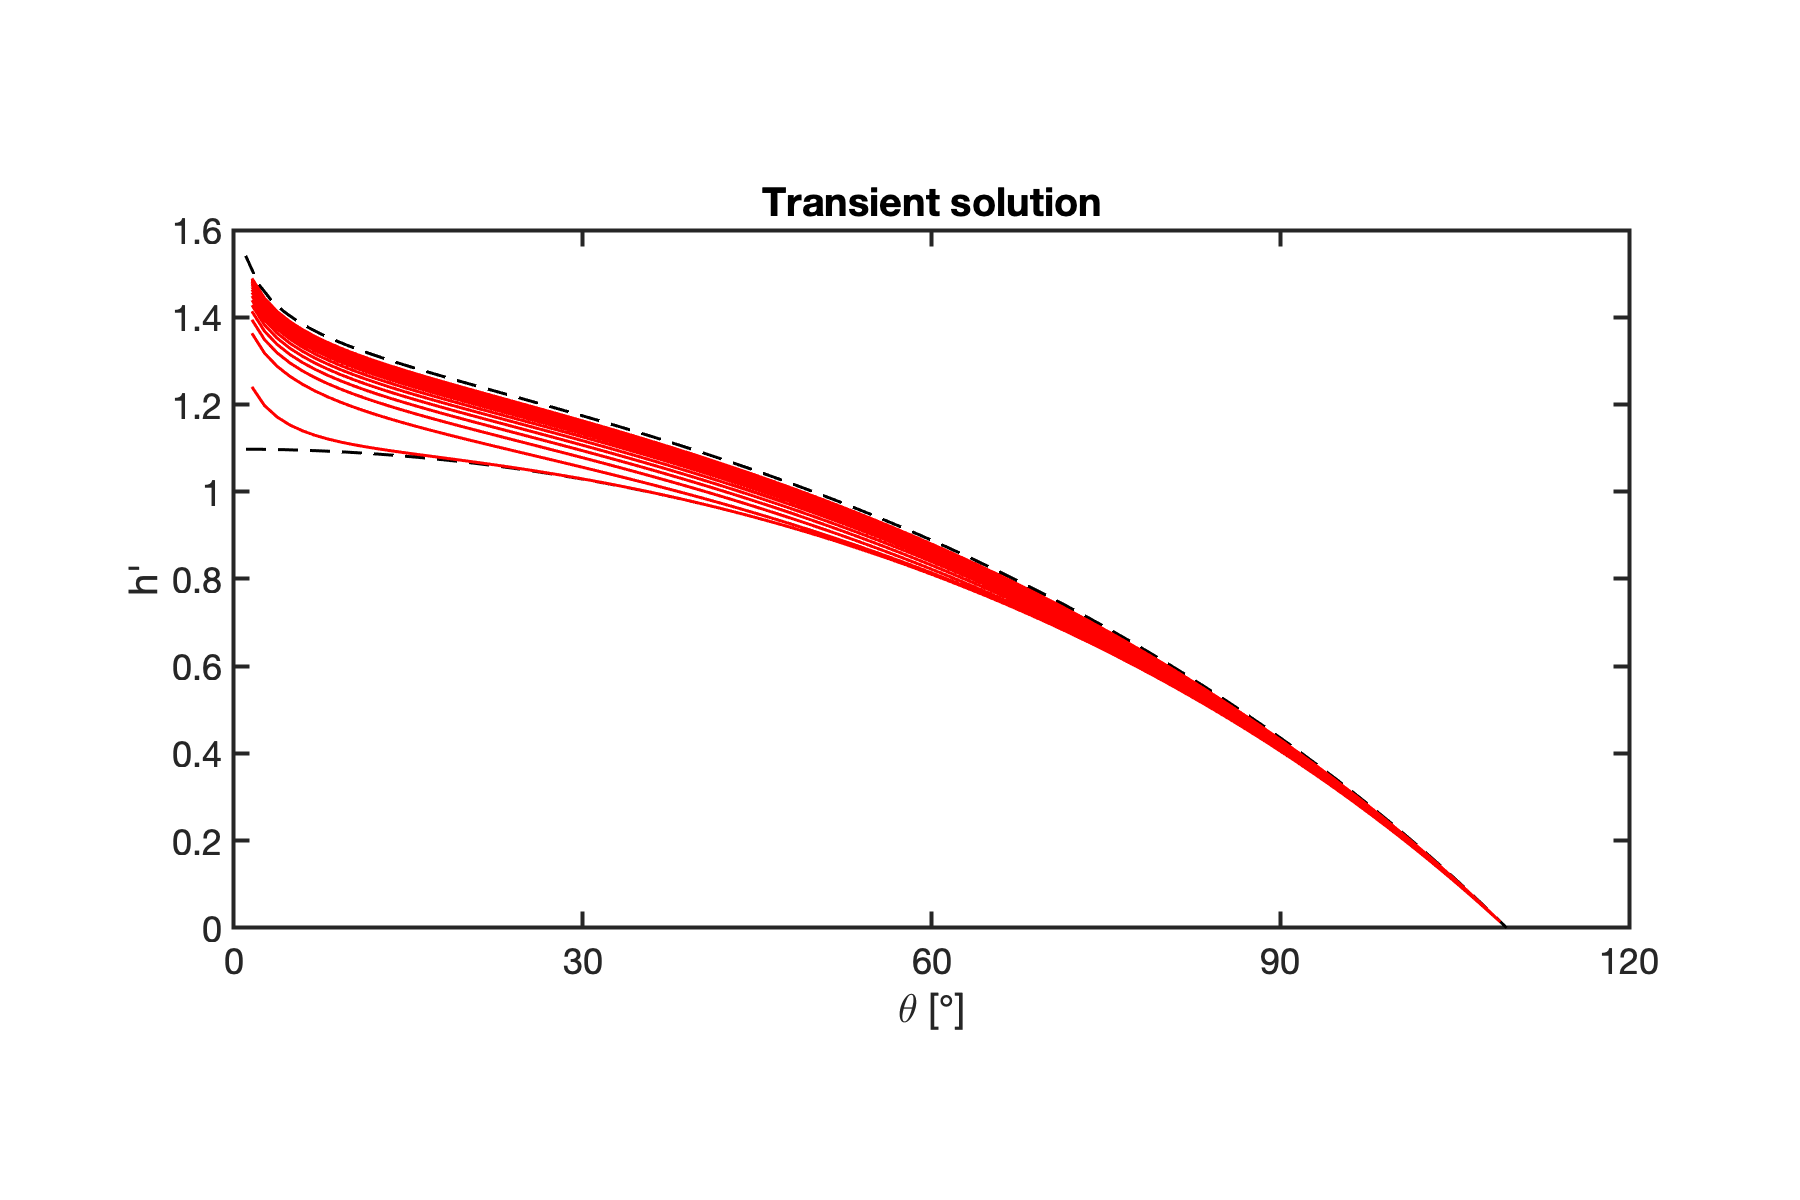

% Temporal parameters
theta_dt = 0;   % this is the theta in the 'Theta method' for timestepping!
tDmax = 2;      % maximum dimensionless time
Nt = 150;
dtD = tDmax/Nt;

% Grid and ops
Grid.xmin = theta_p; Grid.xmax = theta_b; Grid.Nx = 1e2;
Grid.geom = 'spherical_shell';
Grid.R_shell = 1;
Grid = build_grid(Grid);

% Operators
[D,G,I] = build_ops(Grid);
L = -D*G;
IM = I + (1-theta_dt)*dtD*L;
EX = I - theta_dt*dtD*L;
fs = ones(Grid.Nx,1);

%% Boundary conditions
BC.dof_dir = [Grid.dof_xmax];
BC.dof_f_dir = Grid.dof_f_xmax;
BC.g = hD_pre(Grid.xc(Grid.dof_xmax));
BC.dof_neu = Grid.dof_xmin;
BC.dof_f_neu = Grid.dof_f_xmin;
BC.qb = Pi;
[B,N,fn] = build_bnd(BC,Grid,I);

%% Initial condition
hD = hD_pre(Grid.xc);

figure('position',[10 10 900 600])
plot(rad2deg(theta_ana),hD_pre(theta_ana),'k--','linewidth',1.5), hold on
plot(rad2deg(theta_ana),hD_ful(theta_ana,Pi),'k--','linewidth',1.5)

for i=0:Nt
    hD = solve_lbvp(IM,dtD*(fs+fn)+EX*hD,B,BC.g,N);
    if mod(i,10) == 0
        plot(rad2deg(Grid.xc),hD,'r-','linewidth',1.5)
    end
end
set(gca,'xtick',[0:30:120])
pbaspect([1 .8 1])
xlabel('\theta [\circ]','fontsize',14)
ylabel('h''','fontsize',14)
title('Transient solution','fontsize',16)
pbaspect([1 .5 1])

drawnow

The actual timescale this evolution corresponds to on Mars is ~ 72,000 years

yr2s = 60^2*24*365.25; % seconds per year
R = 3389508; % [m] Mars' mean radius 
rho = 1e3;          % [kg/m^3] density of water 
grav = 3.711;       % [m/s^2] grav. acceleration on Mars
k = 1e-11;          % [m^2] permeability (Hanna & Phillips 2005)
mu = 1e-3;          % [Pa s] water viscosity
K = k*rho*grav/mu;   % [m/s] hydraulic conductivity
Ss = rho*grav*1e-9; % [1/m] specific storage
Dhyd = K/Ss;         % [m/s^2] hydraulic diffusivity
tc = R^2/Dhyd/yr2s;          % [s] diffusive timescale
2*tc

ans = 7.2811e+04